[MotionData]=ParseMatlabApp('one_min_control.mat')

MotionData = struct with fields:
            Accel: [617×3 double]
      Orientation: [617×3 double]
           AngVel: [617×3 double]
          t_Accel: [617×1 double]
    t_Orientation: [617×1 double]
         t_AngVel: [617×1 double]
       accel_rate: 10.3093
      orient_rate: 10.3093
      AngVel_rate: 10.3093


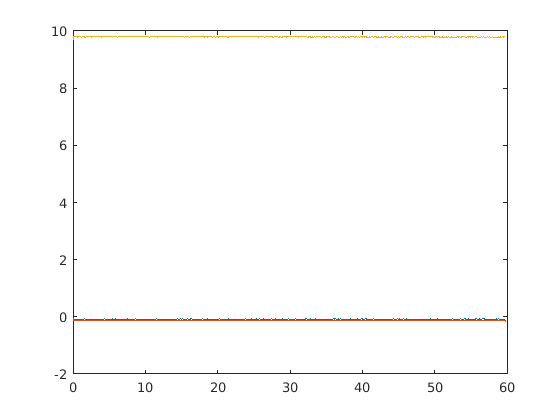

plot(MotionData.t_Accel, MotionData.Accel)

Fs = MotionData.accel_rate

Fs = 10.3093

N = length(MotionData.t_Accel)

N = 617

z_fft = fft(MotionData.Accel(:, 3))

z_fft = 	1.0e+03 *

   6.0423 + 0.0000i
  -0.0001 - 0.0013i
  -0.0003 - 0.0003i
  -0.0004 - 0.0002i
  -0.0001 - 0.0002i
  -0.0001 - 0.0001i
  -0.0001 - 0.0001i
  -0.0003 + 0.0001i
  -0.0002 - 0.0001i
  -0.0002 - 0.0001i


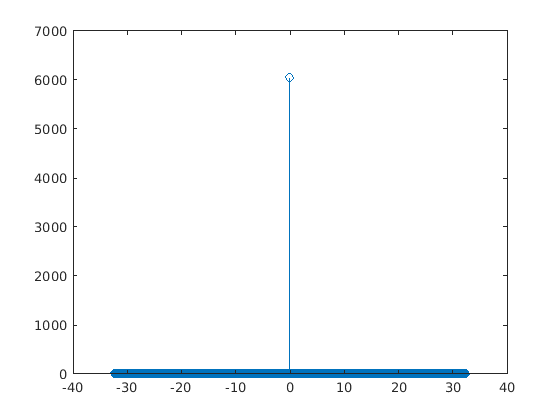

z_fft_shift = fftshift(z_fft);
frequencies_shifted = Fs*linspace(-pi, pi-2/N*pi, N) + pi/N*mod(N,2);

stem(frequencies_shifted, abs(z_fft_shift))


maxk(abs(z_fft), 5)

ans = 	1.0e+03 *

    6.0423
    0.0013
    0.0013
    0.0005
    0.0005


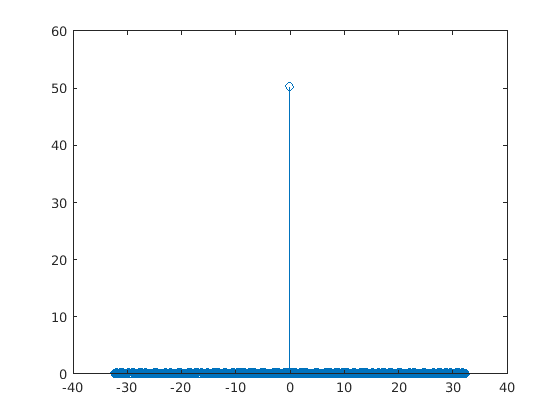

x_fft = fft(MotionData.Accel(:, 1));
x_fft_shift = fftshift(x_fft);
frequencies_shifted = Fs*linspace(-pi, pi-2/N*pi, N) + pi/N*mod(N,2);

stem(frequencies_shifted, abs(x_fft_shift))

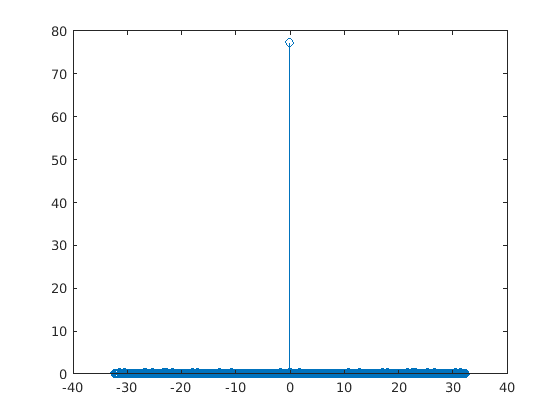

y_fft = fft(MotionData.Accel(:, 2));
y_fft_shift = fftshift(y_fft);
frequencies_shifted = Fs*linspace(-pi, pi-2/N*pi, N) + pi/N*mod(N,2);

stem(frequencies_shifted, abs(y_fft_shift))